% List webcam, capture images and store in folder ranging from 1-10 nos. 
webcamlist

clear('cam');
cam = webcam('/dev/video0');
preview(cam)

savepath = '/home/srb-jarvis/fh_3dimgprocessing/3. Labtask_scripts/cam_calibration';  %the folder
nametemplate = 'image_%02d.jpg';  %name pattern

for K = 1 : 10    %if you want to do this 50 times
   pause(2)
   [YourImage, t] = snapshot(cam)%capture the image
   thisfile = sprintf(nametemplate,K);  %create filename
   fullname = fullfile(savepath, thisfile);  %folder and all
   imwrite( YourImage, fullname);  %write the image there as tif
end

% Detect the corner points of the checker board

imds = imageDatastore("/home/srb-jarvis/fh_3dimgprocessing/3. Labtask_scripts/cam_calibration","FileExtensions",[".jpg",".tif"])

imds =   ImageDatastore with properties:

                       Files: {
                              ' .../fh_3dimgprocessing/3. Labtask_scripts/cam_calibration/image_01.jpg';
                              ' .../fh_3dimgprocessing/3. Labtask_scripts/cam_calibration/image_02.jpg';
                              ' .../fh_3dimgprocessing/3. Labtask_scripts/cam_calibration/image_03.jpg'
                               ... and 7 more
                              }
                     Folders: {
                              '/home/srb-jarvis/fh_3dimgprocessing/3. Labtask_scripts/cam_calibration'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



[imagePoints,boardSize,imagesUsed] = detectCheckerboardPoints(imds.Files(1:10))

imagePoints = imagePoints(:,:,1) =

  464.7469  344.0754
  463.5215  377.4818
  462.3691  411.1056
  461.4481  444.9382
  460.6417  479.0625
  459.9078  513.2505
  459.0973  547.6158
  497.5791  344.1547
  496.4121  377.8380
  495.4618  411.6136
  494.6277  445.6949
  493.8896  479.8973
  493.1640  514.1125
  492.4846  548.5856
  530.6389  344.3427
  529.6776  378.0146
  528.7147  412.0630
  527.9854  446.1275
  527.2774  480.6264
  526.8516  514.9573
  526.1304  549.4574
  564.1919  344.5763
  563.3016  378.3307
  562.5693  412.4240
  561.8239  446.7740
  561.2744  481.2306
  560.5395  515.6926
  560.1686  550.3162
  597.9443  344.7874
  597.2533  378.6893
  596.6072  412.8904
  595.9418  447.2400
  595.3358  481.9372
  594.9505  516.4849
  594.3867  551.1602
  632.1038  344.9456
  631.6407  379.0510
  631.0648  413.2385
  630.5836  447.8127
  629.9944  482.4118
  629.4733  517.1046
  629.0923  551.8598
  666.2045  345.3135
  665.8628  379.3785
  665.2819  413.7286
  664.9417  448.166

boardSize =      8    11


imagesUsed = 10×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


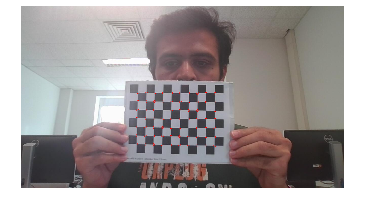

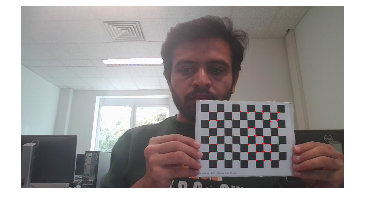

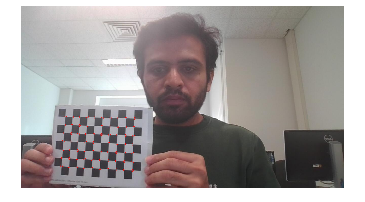

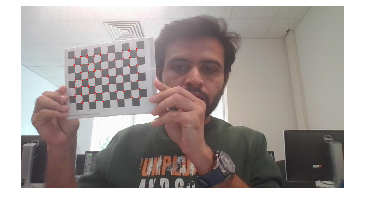

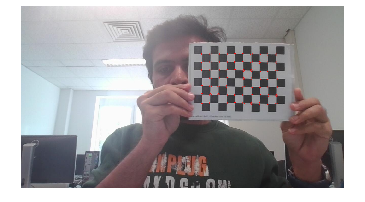

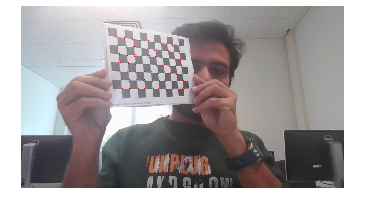

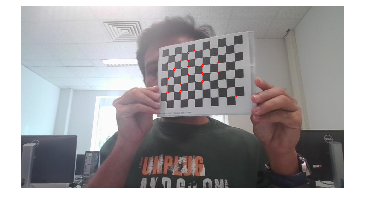

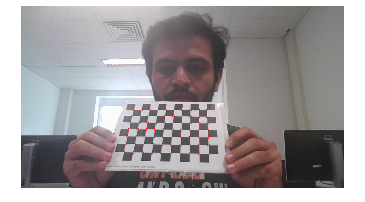


for i = 1:10
  % Read image
  I = readimage(imds, i);

  % Insert markers at detected point locations
  I = insertMarker(I, imagePoints(:,:,i), 'o','Color','red', 'Size', 4);

  % Display image
  figure
  imshow(I)
end

% Transform the image points from the corner points into world coordinates
squareSize = 15; % millimeters
worldPoints = generateCheckerboardPoints(boardSize,squareSize)

worldPoints =      0     0
     0    15
     0    30
     0    45
     0    60
     0    75
     0    90
    15     0
    15    15
    15    30


% Calculate the intrinsic and extrinsic camera parameters
[cameraParams,imagesUsed,estimationErrors] = estimateCameraParameters(imagePoints,worldPoints)

cameraParams =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [0×0 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [10×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.3437
                 ReprojectionErrors: [70×2×10 double]
                  ReprojectedPoints: [70×2×10 double]

   Calibration Settings
                        NumPatterns: 10
                  DetectedKeypoints: [70×10 logical]
                        WorldPoints: [70×2 double]
                         WorldUnits: 'mm'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


imagesUsed = 10×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


estimationErrors =   cameraCalibrationErrors with properties:

    IntrinsicsErrors: [1×1 intrinsicsEstimationErrors]
    ExtrinsicsErrors: [1×1 extrinsicsEstimationErrors]


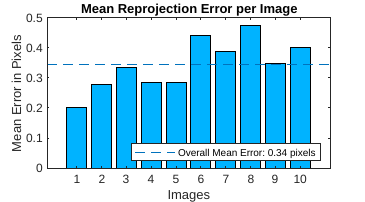

showReprojectionErrors(cameraParams)

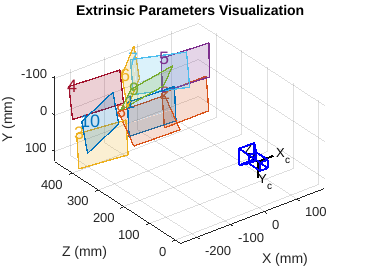

% Show the checker board positions with the perspective of the camera coordinate origin
figure;
showExtrinsics(cameraParams);